## Importar las señales necesarias

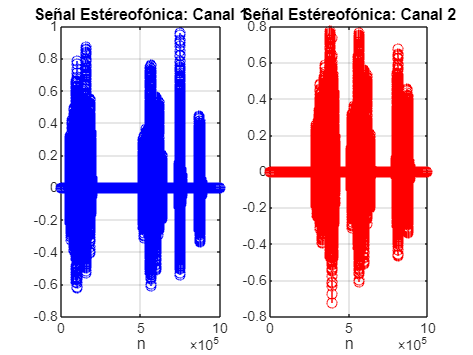

function [signal, sample_rate] = import_signal()
    % Busca el archivo que se quiere importar
    [filename, path] = uigetfile({'*.mp3;*.wav'}); 
    % figure(app.UIFigure);
    fullFileName = fullfile(path, filename);  % Construye la ruta completa del archivo
    
    % Recuperar los datos importados
    [signal, sample_rate] = audioread(fullFileName);
end

function plot_the_signal(stereo_signal)
    figure
    subplot(1,2,1); stem(stereo_signal(:,1),'b');grid on;
    title('Señal Estéreofónica: Canal 1'); xlabel('n');
    subplot(1,2,2); stem(stereo_signal(:,2),'r');grid on;
    title('Señal Estéreofónica: Canal 2'); xlabel('n');
end

[stereo_signal, sample_rate] = import_signal();

plot_the_signal(stereo_signal);


sound(stereo_signal, sample_rate);

## Preprocesamiento

preprocessed_signal = preprocesamiento(stereo_signal);

You are using the normalize function


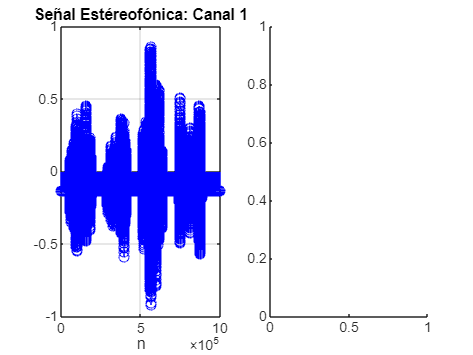

Index in position 2 exceeds array bounds. Index must not exceed 1.

Error in script_de_prueba>plot_the_signal (line 15)
    subplot(1,2,2); stem(stereo_signal(:,2),'r');grid on;


plot_the_signal(preprocessed_signal);


sound(preprocessed_signal, sample_rate);

## Procesamiento